f=@(x,y) x+y;
x0=0;xn=2;y0=1;n=5;
[y1,x1]=RK_2(f,n,x0,xn,y0);
[y2,x2]=RK_4(f,n,x0,xn,y0);
[y3,x3]=Euler(f,n,x0,xn,y0);
syms t
y_z = dsolve("Dy==t+y","y(0)=1",t);

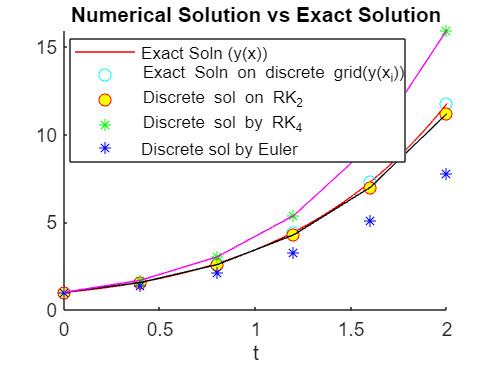

y_x = double(subs(y_z,t,x1));
hold on
h=ezplot(y_z,[x0,xn]);
set(h,'Color','red');
scatter(x1,y_x,"c")
xlim auto
ylim auto
scatter(x1,y1,"MarkerEdgeColor","red","MarkerFaceColor","yellow");
scatter(x2,y2,"green","*");
scatter(x3,y3,"blue","*");
plot(x1,y1,"black")
plot(x2,y2,"yellow")
plot(x3,y2,"magenta")
lgd=legend("Exact Soln (y(x))","Exact Soln on discrete grid(y(x_i))","Discrete sol on RK_2","Discrete sol by RK_4","Discrete sol by Euler","","","");
lgd.Location="best";
title("Numerical Solution vs Exact Solution");
hold off

x=x1';y_ex=y_x';y_RK2=y1';y_RK4=y2';y_el=y3';
table(x,y_ex,y_RK2,y_RK4,y_el)

ans = 6×5 table
     x      y_ex     y_RK2     y_RK4      y_el 
    ___    ______    ______    ______    ______

      0         1         1         1         1
    0.4    1.5836      1.56    1.6896       1.4
    0.8    2.6511    2.5808    3.0237      2.12
    1.2    4.4402    4.2836    5.3834     3.288
    1.6    7.3061    6.9957    9.3753    5.0832
      2    11.778    11.202    15.965    7.7565


error_RK2=double(abs(y1-y_x))';
error_RK4=double(abs(y3-y_x))';
error_el=double(abs(y3 -y_x))';
table(error_RK4,error_RK2,error_el)

ans = 6×3 table
    error_RK4    error_RK2    error_el
    _________    _________    ________

           0            0           0 
     0.18365     0.023649     0.18365 
     0.53108     0.070282     0.53108 
      1.1522      0.15665      1.1522 
      2.2229      0.31036      2.2229 
      4.0216      0.57647      4.0216 
